# Input:

% ad = '/MATLAB Drive/O/B o/0 GPS.txt';
% File path of the file
% Roof of the red car, target: ...+65 extrn
% 35 - 99 imgs

% t = 'O/Data/0 Car h a.data';
ld = 35;
% t = 'O/Data/0 tree.data';
% t = 'O/Data/3 Car r m.data'; ld = 22;

% house 36 + px, 99 imgs+
% pix = 'O/Data/pix.data';
m = 65; ldp = 37; tr = 21;
% pix = 'O/Data/0 tree pix.data';
% pix = 'O/Data/3 Red car m pix.data';
% m = 58;
% ldp = 44; tr = 31;
% tr = 101;

tbl = readtable(t, ...
    'Filetype', 'text', ...
    'ReadVariableNames',false);
ptbl = readtable(pix, 'Filetype', 'text');
% 66 house+
tbl.Properties.VariableNames = {
    'Altitude', 'Latitude', ['' ...
    'Longitude'], ...
    'PixelX', 'PixelY', 'Ylatitude'};

fprintf('Address: %s', ad)

Address: /MATLAB Drive/O/B o/0 GPS.txt

tbl(1:7,:)

ans = 7x6 table
    Altitude    Latitude    Longitude    PixelX    PixelY    Ylatitude
    ________    ________    _________    ______    ______    _________

     122.66      47.641      -122.14        0         0       47.641  
     297.01      47.638      -122.14      342       253       47.638  
     298.75      47.638      -122.14      342       260       47.638  
     301.36      47.638      -122.14      342       261       47.638  
      303.2      47.638      -122.14      342       262       47.638  
     304.84      47.638      -122.14      342       263       47.638  
     307.29      47.638      -122.14      342       265       47.638  


% tbl.Ycoordinate = tbl.;
% Display the first seven rows.
ptbl(1:7,:)

ans = 7x2 table
    PixelX    PixelY
    ______    ______

     338       208  
     337       209  
     337       210  
     338       211  
     338       211  
     337       212  
     337       213  


% fread(fopen('/MATLAB Drive/Sir.txt', ...
%     'r'),'*char')'

# Display:

format long
% format shortG

## Altitudes, Longitudes, L`atitude`:

% 47.6419266928565-la(1)
% 47.6419266928565-l(1)

% idx = randperm(480) % 10

idx =    183   453   134   427   296    51   351   112    12    89   365   127   258    40   144   287   187   208   106   322   313   267   220   320    79   448    63   469   132   328   467   380   168   297   449   129   103   310   455    28   207   203   218    24   145   201   431    43   308   302


% save("O/Data/r480.mat","idx") % ,"q"

% save("id.mat","py","px","tltsa"
% ,"tltra", ...
%     "tlts","tltr","tla","tlltr","
% -append")

% load("id.mat")
% whos("-file","id.mat")
% load("O/Data/r80.mat")
% whos("-file","O/Data/r80.mat")
load("O/Data/r480.mat")
whos("-file","O/Data/r480.mat")

  Name      Size             Bytes  Class     Attributes

  idx       1x480             3840  double              



# Latitude table:

tbl(2:end, end).Variables = tbl(1, ...
    2).Variables*ones(ld,1);

The end operator must be used within an array index expression.

% tla = [table(a(ldp:end),lo(ldp:end), ...
%     l(ldp:end),ptbl(:,1).Variables, ...
%     ptbl(:,2).Variables, ...
%     tbl(1, 2).Variables*ones(m,1),['' ...
%     'VariableNames'],{'Altitude', ...
%     'Longitude', 'Latitude', 'PixelX', ...
%     'PixelY', 'Ylatitude'});
% tbl(2:end, :)];

d = 'O/Data/';
t1a = readtable([d '1a Car c.txt'], ...
    'Filetype', 'text');

tla = [t1a(2:end, :); readtable([d ...
    '2a Car h a.txt'], ...
    'Filetype', 'text'); readtable([d ...
    '3a car r m.txt'], ...
    'Filetype', 'text'); readtable([d ...
    '4a Tree.txt'], ...
    'Filetype', 'text'); readtable([d ...
    '5a H.txt'], 'Filetype', 'text')];

fprintf(['Drone data, output: Latitude\n' ...
    '9 of 100 rows, 3 of 5 cols']);

Drone data, output: Latitude
9 of 100 rows, 3 of 5 cols

tla(2:10,:)

ans = 9x6 table
    Altitude    Longitude    Latitude    PixelX    PixelY    Ylatitude
    ________    _________    ________    ______    ______    _________

     219.39      -122.14      47.637      339       190       47.641  
      220.4      -122.14      47.637      339       191       47.641  
     221.59      -122.14      47.637      339       191       47.641  
     222.93      -122.14      47.637      339       191       47.641  
      224.2      -122.14      47.637      339       192       47.641  
     225.78      -122.14      47.637      339       192       47.641  
     227.19      -122.14      47.637      339       193       47.641  
        228      -122.14      47.637      339       194       47.641  
     229.87      -122.14      47.637      339       195       47.641 

ans =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


tltr = tla(sort(idx(tr:end)),:);
tltr(2:10,[1 3 end])

ans = 9x3 table
    Altitude    Latitude    Ylatitude
    ________    ________    _________

     174.82      47.642      47.642  
      176.5      47.642      47.642  
     177.91      47.642      47.642  
     178.61      47.642      47.642  
     180.37      47.642      47.642  
     181.26      47.642      47.642  
      182.8      47.642      47.642  
     184.01      47.642      47.642  
      185.7      47.642      47.642  


tlts = tla(sort(idx(1:tr-1)),:);
tlts(2:10,[1 3 end])

ans = 9x3 table
    Altitude    Latitude    Ylatitude
    ________    ________    _________

        188      47.642      47.642  
     197.42      47.642      47.642  
     203.18      47.642      47.642  
     206.94      47.642      47.642  
     208.89      47.642      47.642  
     210.83      47.642      47.642  
     212.25      47.642      47.642  
     218.01      47.642      47.642  
     222.93      47.642      47.642  


## Longitude table:

tl = tla;
tl(:,"Ylatitude").Variables = tbl(1, ...
    3).Variables*ones(m+ld,1);
tl.Properties.VariableNames{end} = ['' ...
    'Ylongitude'];
fprintf('Output: Longitude');tl(2:10,:)

Output: Longitude

ans = 9x6 table
    Altitude    Longitude    Latitude    PixelX    PixelY    Ylongitude
    ________    _________    ________    ______    ______    __________

        228      -122.14      47.637      337       209       -122.14  
     229.87      -122.14      47.637      337       210       -122.14  
     230.26      -122.14      47.637      338       211       -122.14  
     231.67      -122.14      47.637      338       211       -122.14  
     233.23      -122.14      47.637      337       212       -122.14  
     234.26      -122.14      47.637      337       213       -122.14  
     235.42      -122.14      47.637      337       214       -122.14  
     236.84      -122.14      47.637      338       215       -122.14  
     237.86      -122.14      47.637      338       215    

t1o = readtable([d '1o Car c.txt'], ...
    'Filetype', 'text');

tl = [t1o(2:end, :); readtable([d ...
    '2o Car h a.txt'], ...
    'Filetype', 'text'); readtable([d ...
    '3o car r m.txt'], ...
    'Filetype', 'text'); readtable([d ...
    '4o Tree.txt'], ...
    'Filetype', 'text'); readtable([d ...
    '5o H.txt'], 'Filetype', 'text')];

tlltr = tl(sort(idx(tr:end)),:);
tlltr(2:10,[1 3 end])

ans = 9x3 table
    Altitude    Latitude    Ylongitude
    ________    ________    __________

     174.82      47.642      -122.14  
      176.5      47.642      -122.14  
     177.91      47.642      -122.14  
     178.61      47.642      -122.14  
     180.37      47.642      -122.14  
     181.26      47.642      -122.14  
      182.8      47.642      -122.14  
     184.01      47.642      -122.14  
      185.7      47.642      -122.14  


tllts = tl(sort(idx(1:tr-1)),:);
tllts(2:10,[1 3 end])

ans = 9x3 table
    Altitude    Latitude    Ylongitude
    ________    ________    __________

        188      47.642      -122.14  
     197.42      47.642      -122.14  
     203.18      47.642      -122.14  
     206.94      47.642      -122.14  
     208.89      47.642      -122.14  
     210.83      47.642      -122.14  
     212.25      47.642      -122.14  
     218.01      47.642      -122.14  
     222.93      47.642      -122.14  


# Longitude gpr:

% cross-validation:
% rng('default') % For reproducibility
gprMdlo = fitrgp(tlltr, ...
    'Ylongitude', ...
    'KernelFunction', ...
    'ardsquaredexponential',...
      'FitMethod','sr','PredictMethod', ...
      'fic','Standardize',1,'Sigma',.002)

gprMdlo =   RegressionGP
           PredictorNames: {'Altitude'  'Longitude'  'Latitude'  'PixelX'  'PixelY'}
             ResponseName: 'Ylongitude'
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 380
           KernelFunction: 'ARDSquaredExponential'
        KernelInformation: [1x1 struct]
            BasisFunction: 'Constant'
                     Beta: -122.1395
                    Sigma: 0.0010
        PredictorLocation: [5x1 double]
           PredictorScale: [5x1 double]
                    Alpha: [380x1 double]
         ActiveSetVectors: [380x5 double]
            PredictMethod: 'FIC'
            ActiveSetSize: 380
                FitMethod: 'SR'
          ActiveSetMethod: 'Random'
        IsActiveSetVector: [380x1 logical]
            LogLikelihood: 2.2685e+03
         ActiveSetHistory: [1x1 struct]
           BCDInformation: []


  Properties

% ...
    %   'Standardize',1, ...
    % 'Sigma',.002)
% fprintf('kfoldLoss = %e', kfoldLoss( ...
%     cvgprMdl))
% ypred = kfoldPredict(cvgprMdl);
% fprintf('kfoldPredict: ');
% fprintf('%f\t', ypred')

ypredlo = predict(gprMdlo,tllts(:, ...
    1:end-1).Variables);ypredlo'

ans =  -122.1401 -122.1401 -122.1401 -122.1401 -122.1401 -122.1401 -122.1401 -122.1401 -122.1401 -122.1401 -122.1401 -122.1401 -122.1401 -122.1401 -122.1401 -122.1401 -122.1401 -122.1401 -122.1401 -122.1401 -122.1401 -122.1401 -122.1385 -122.1385 -122.1385 -122.1385 -122.1385 -122.1385 -122.1385 -122.1385 -122.1385 -122.1385 -122.1385 -122.1385 -122.1385 -122.1385 -122.1385 -122.1385 -122.1384 -122.1384 -122.1384 -122.1384 -122.1384 -122.1384 -122.1384 -122.1384 -122.1384 -122.1384 -122.1384 -122.1384


% elo = (lo(1)-ypredlo(1))/lo(1) %

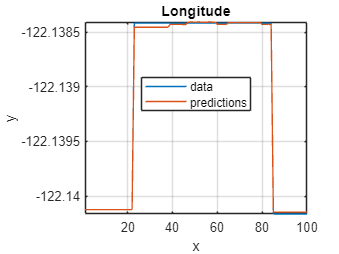

figure(); % ,'b.'
plot(tllts(:, ...
    end).Variables);
% tlltr(1:tr-1,"Ylongitude").Ylongitude
axis tight
xlabel('x')
ylabel('y')
hold on;
plot(ypredlo);
hold off;
grid on
legend({'data','predictions'}, ...
    'Location','Best');
title('Longitude')

# Laltitude gpr:

% cross-validation:
% rng('default') % For reproducibility
gprMdll = fitrgp(tltr, 'Ylatitude', ...
    'KernelFunction', ...
    'ardsquaredexponential',...
      'FitMethod','sr','PredictMethod', ...
      'fic','Standardize',1,'Sigma',.002)

gprMdll =   RegressionGP
           PredictorNames: {'Altitude'  'Longitude'  'Latitude'  'PixelX'  'PixelY'}
             ResponseName: 'Ylatitude'
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 380
           KernelFunction: 'ARDSquaredExponential'
        KernelInformation: [1x1 struct]
            BasisFunction: 'Constant'
                     Beta: 47.6401
                    Sigma: 0.0010
        PredictorLocation: [5x1 double]
           PredictorScale: [5x1 double]
                    Alpha: [380x1 double]
         ActiveSetVectors: [380x5 double]
            PredictMethod: 'FIC'
            ActiveSetSize: 380
                FitMethod: 'SR'
          ActiveSetMethod: 'Random'
        IsActiveSetVector: [380x1 logical]
            LogLikelihood: 2.2630e+03
         ActiveSetHistory: [1x1 struct]
           BCDInformation: []


  Properties, <

% ...
    %   'Standardize',1, ...
    % 'Sigma',.002)
% fprintf('kfoldLoss = %e', kfoldLoss( ...
%     cvgprMdl))
% ypred = kfoldPredict(cvgprMdl);
% fprintf('kfoldPredict: ');
% fprintf('%f\t', ypred')

ypredl = predict(gprMdll,tlts(:,1:end- ...
    1).Variables);ypredl'

ans =    47.6419   47.6419   47.6419   47.6419   47.6419   47.6419   47.6419   47.6419   47.6419   47.6419   47.6419   47.6419   47.6419   47.6419   47.6419   47.6419   47.6419   47.6419   47.6419   47.6419   47.6419   47.6419   47.6412   47.6412   47.6412   47.6412   47.6412   47.6412   47.6412   47.6412   47.6412   47.6412   47.6412   47.6412   47.6412   47.6412   47.6412   47.6412   47.6412   47.6412   47.6412   47.6412   47.6412   47.6412   47.6412   47.6412   47.6412   47.6412   47.6412   47.6412


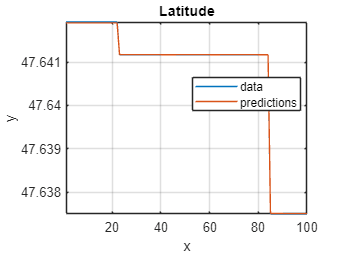

% el = (l(1)-ypredl(1))/l(1)

figure(); % ,'b.'
plot(tlts(:, ...
    end).Variables);
% tlltr(1:tr-1,"Ylongitude").Ylongitude
axis tight
xlabel('x')
ylabel('y')
hold on;
plot(ypredl);
hold off;
grid on
legend({'data','predictions'}, ...
    'Location','Best');
title('Latitude')

d1km = zeros(1, tr-1);
d2km = d1km;
for i = 1:tr-1
    [d1km(i), d2km(i)] = lldistkm( ...
        [tlts(i, end ...
    ).Variables tllts(i, end ...
    ).Variables], ...
    [ypredl(i) ypredlo(i)]);
end

[d1km; d2km]*1000
save("/MATLAB Drive/O/B o/dist." + ...
    "mat","d2","-append")

[m, i] = min(d1km*1000); 
[M, I] = max(d1km*1000);
[m2,i2] = min(d2km*1000);
[M2,I2] = max(d2km*1000);
{m, M, m2, M2; i, I, i2, I2}'

ans = 4x2 cell array
    {[0.8892]}    {[65]}
    {[2.9340]}    {[23]}
    {[0.8892]}    {[65]}
    {[2.9340]}    {[23]}


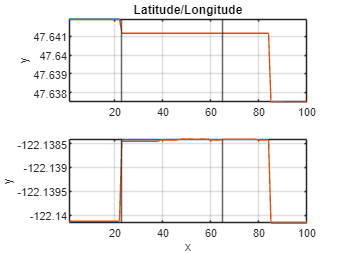

figure(); % ,'b.'
subplot(2,1,1);
plot(tlts(:, ...
    end).Variables);
% tlltr(1:tr-1,"Ylongitude").Ylongitude
axis tight
ylabel('y')
hold on;
plot(ypredl);
hold off;
grid on
% legend({'dataA','predA'}, ...
%     'Location','Best');
title('Latitude/Longitude')
xline([i,I])

subplot(2,1,2); 
plot(tllts(:, ...
    end).Variables);
axis tight
xlabel('x')
ylabel('y')
hold on;
plot(ypredlo);
hold off;
grid on
% legend({'dataL','predL'}, ...
%     'Location','Best');
xline([i,I])

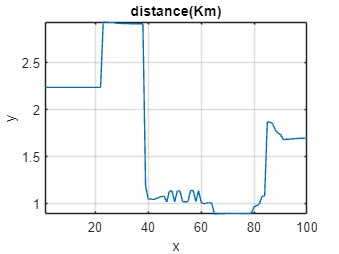

figure(); % ,'b.'
plot(d1km*1000);
% tlltr(1:tr-1,"Ylongitude").Ylongitude
axis tight
xlabel('x')
ylabel('y')
grid on
title('distance(Km)')

[d11km, d12km] = lldistkm([tlts(1, end ...
    ).Variables tllts(1, end ...
    ).Variables], ...
    [ypredl(1) ypredlo(1)])

d11km = 0.0022

d12km = 0.0022

ans =     0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0012    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011    0.0011    0.0010    0.0011    0.0011    0.0010
    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0022    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0012    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011    0.0011    0.0010    0.0011    0.0011   

ans =     2.2373    2.2373    2.2373    2.2373    2.2373    2.2373    2.2373    2.2373    2.2373    2.2373    2.2373    2.2374    2.2374    2.2374    2.2375    2.2375    2.2377    2.2378    2.2379    2.2379    2.2379    2.2380    2.9340    2.9323    2.9311    2.9302    2.9265    2.9204    2.9192    2.9185    2.9176    2.9170    2.9153    2.9151    2.9148    2.9146    2.9145    2.9134    1.1931    1.0471    1.0490    1.0433    1.0537    1.0641    1.0761    1.0771    1.0163    1.1338    1.1344    1.0175
    2.2373    2.2373    2.2373    2.2373    2.2373    2.2373    2.2373    2.2373    2.2373    2.2373    2.2373    2.2374    2.2374    2.2374    2.2375    2.2375    2.2377    2.2378    2.2379    2.2379    2.2379    2.2380    2.9340    2.9323    2.9311    2.9302    2.9265    2.9204    2.9192    2.9185    2.9176    2.9170    2.9153    2.9151    2.9148    2.9146    2.9145    2.9134    1.1931    1.0471    1.0490    1.0433    1.0537    1.0641    1.0761    1.0771    1.0163    1.1338    1.1344   

ans = 4x2 cell array
    {[0.8892]}    {[65]}
    {[2.9340]}    {[23]}
    {[0.8892]}    {[65]}
    {[2.9340]}    {[23]}


[d21km, d22km] = lldistkm([tla(1, end ...
    ).Variables tlltr(1, end ...
    ).Variables], ...
    [ypredl(1) ypredlo(1)])

[d1km, d2km] = lldistkm([tla(1, end ...
    ).Variables tlltr(1, end ...
    ).Variables], ...
    [ypredl(1) ypredlo(1)])

d1km*1000 % m

ans = 7.6579e-09

% writetable(tla,['O/Data/4a Tree.' ...
%     'txt'],'Delimiter',' ') % All Car h a
open 'O/Data/2a Car h a.txt'

% writetable(tl,'O/Data/4o Tree.txt',['' ...
%     'Delimiter'],' ') % Alll Car h a